clc

clear

rng(42)

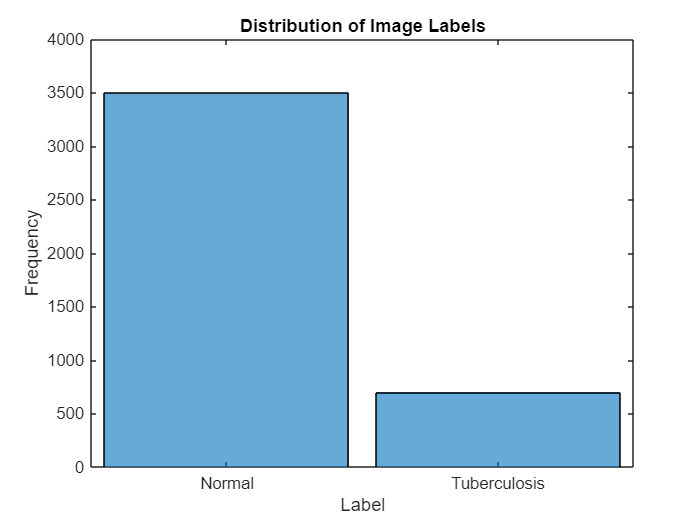

rng(42)
% Load the image datastore
LungImds = imageDatastore("C:\Users\Avrajit\Downloads\TB_Chest_Radiography_Database", "IncludeSubfolders", true, "LabelSource", "foldernames");

% Count number of observations per class
numObs = length(LungImds.Labels);
numObsPerClass = countEachLabel(LungImds);

% Display class distribution histogram
figure;
histogram(LungImds.Labels);
title('Distribution of Image Labels');
xlabel('Label');
ylabel('Frequency');
ylim([0,4000]);
set(gca, 'TickLabelInterpreter', 'none');

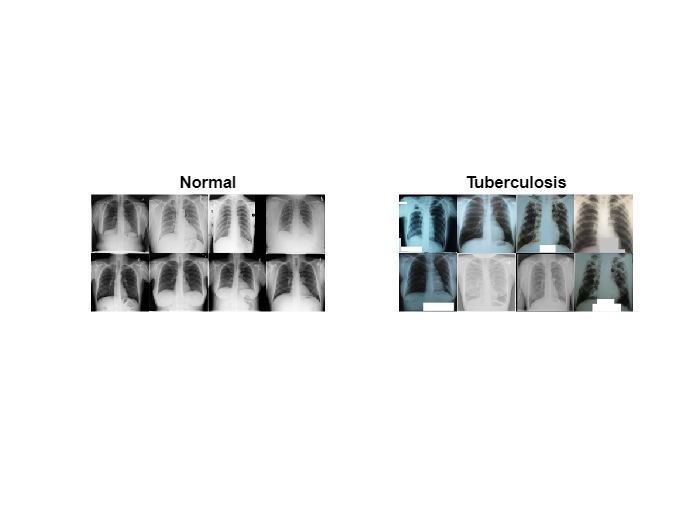


% Example: Show random images from each class
numObsToShow = 8;
subplot(1,2,1)
% Display random Normal class images
class = "Normal";
idxClass = find(LungImds.Labels == class);
idx = randsample(idxClass, numObsToShow);
imshow(imtile(LungImds.Files(idx), 'GridSize', [2 4], 'ThumbnailSize', [100 100]));
title("Normal")
% Display random Tuberculosis class images
subplot(1,2,2)
class = "Tuberculosis";
idxClass = find(LungImds.Labels == class);
idx = randsample(idxClass, numObsToShow);
imshow(imtile(LungImds.Files(idx), 'GridSize', [2 4], 'ThumbnailSize', [100 100]));
title("Tuberculosis")

% Process all images: Compute 2D DCT and filter
rng(42)
numImages = numel(LungImds.Files);
fourierTransforms = cell(numImages, 1);
totalTime = tic;  % Start measuring total time
for i = 1:numImages
    imgTime = tic;  % Start measuring time for each image
    
    % Read image and convert to grayscale if RGB
    img = readimage(LungImds, i);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    
    % Compute 2D DCT
    F = (dct2(double(img)));
    
    fourierTransforms{i} = abs(F);
    
    % Display time taken for the current image
    fprintf('Time taken for image %d: %.4f seconds\n', i, toc(imgTime));
end

Time taken for image 1: 0.2294 seconds
Time taken for image 2: 0.0309 seconds
Time taken for image 3: 0.0350 seconds
Time taken for image 4: 0.0340 seconds
Time taken for image 5: 0.0394 seconds
Time taken for image 6: 0.0259 seconds
Time taken for image 7: 0.0239 seconds
Time taken for image 8: 0.0262 seconds
Time taken for image 9: 0.0246 seconds
Time taken for image 10: 0.0256 seconds
Time taken for image 11: 0.0263 seconds
Time taken for image 12: 0.0251 seconds
Time taken for image 13: 0.0268 seconds
Time taken for image 14: 0.0270 seconds
Time taken for image 15: 0.0242 seconds
Time taken for image 16: 0.0246 seconds
Time taken for image 17: 0.0250 seconds
Time taken for image 18: 0.0249 seconds
Time taken for image 19: 0.0277 seconds
Time taken for image 20: 0.0265 seconds
Time taken for image 21: 0.0262 seconds
Time taken for image 22: 0.0255 seconds
Time taken for image 23: 0.0265 seconds
Time taken for image 24: 0.0279 seconds
Time taken for image 25: 0.0270 seconds
Time take


% Display total time taken for the entire loop
fprintf('Total time for all images: %.4f seconds\n', toc(totalTime));

Total time for all images: 127.1703 seconds



% Prepare data for neural network input (flatten 2D into 1D)
X = zeros(numImages, numel(fourierTransforms{1}));
for i = 1:numImages
    X(i, :) = fourierTransforms{i}(:)';
end
Y = categorical(LungImds.Labels);

% Split data into training (70%), validation (15%), and testing (15%) sets by preserving class distribution
rng(42)
cv = cvpartition(Y, 'Holdout', 0.3, 'Stratify', true); % 30% holdout for validation + testing
XTrain = X(cv.training, :);
YTrain = Y(cv.training);

% Split the remaining 30% into validation and test sets (50-50 split) while preserving class distribution
XRemain = X(cv.test, :); % The remaining 30% data
YRemain = Y(cv.test);

cv2 = cvpartition(YRemain, 'Holdout', 0.5, 'Stratify', true);
XVal = XRemain(cv2.training, :);
YVal = YRemain(cv2.training);
XTest = XRemain(cv2.test, :);
YTest = YRemain(cv2.test);

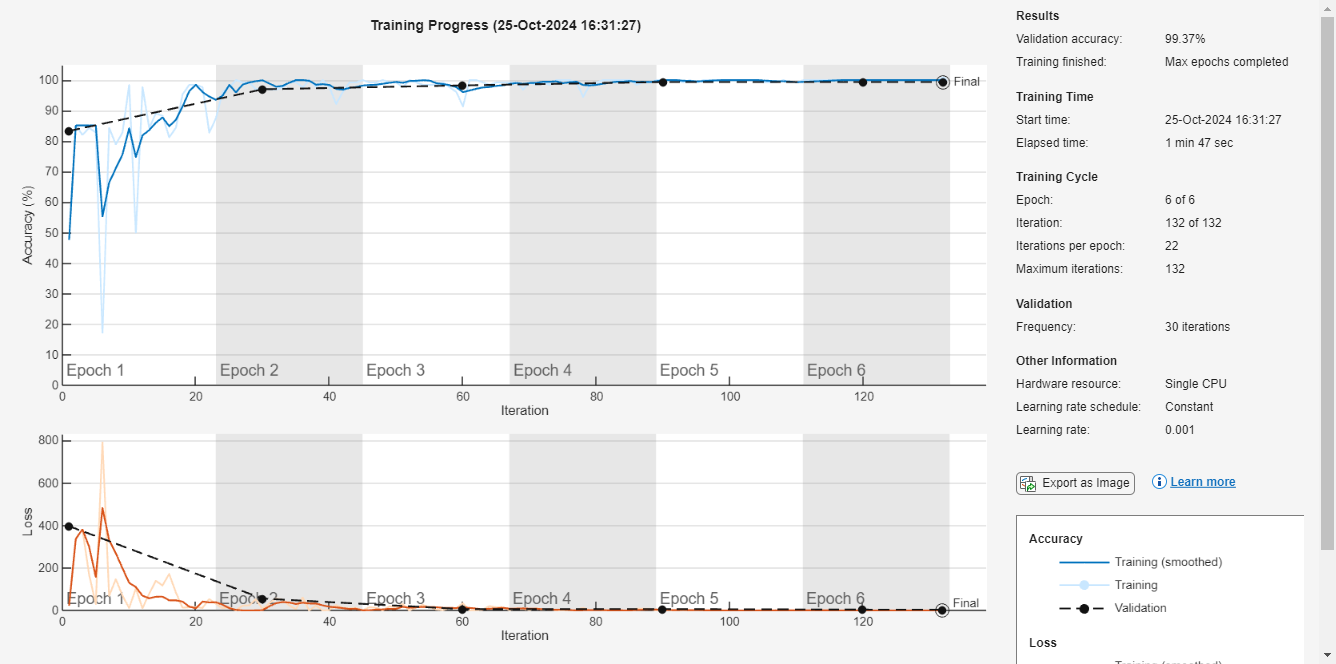


% Define the neural network architecture
rng(42)
layers = [
    featureInputLayer(size(XTrain, 2))
    fullyConnectedLayer(100)
    reluLayer
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(2)  % Adjust for the number of classes
    softmaxLayer
    classificationLayer
];

% Set training options
options = trainingOptions('adam', ...
    'MaxEpochs', 6, ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress');  % Optional early stopping

[net, trainingInfo] = trainNetwork(XTrain, YTrain, layers, options);

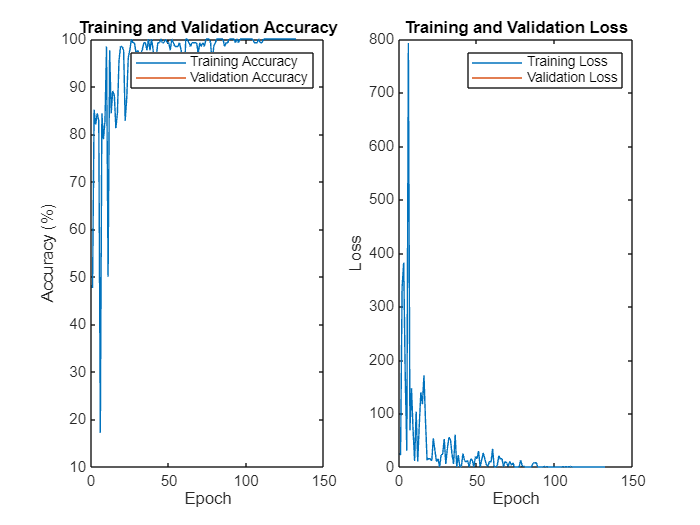

% Extract relevant fields
epochs = 1:length(trainingInfo.TrainingLoss);  % Number of epochs
trainAcc = trainingInfo.TrainingAccuracy;      % Training accuracy for each epoch
valAcc = trainingInfo.ValidationAccuracy;      % Validation accuracy for each epoch
trainLoss = trainingInfo.TrainingLoss;         % Training loss for each epoch
valLoss = trainingInfo.ValidationLoss;         % Validation loss for each epoch

% Plot accuracy (training vs validation)
figure;
subplot(1, 2, 1);
plot(epochs, trainAcc);
hold on;
plot(epochs, valAcc);
xlabel('Epoch');
ylabel('Accuracy (%)');
title('Training and Validation Accuracy');
legend('Training Accuracy', 'Validation Accuracy');
hold off;

% Plot loss (training vs validation)
subplot(1, 2, 2);
plot(epochs, trainLoss);
hold on;
plot(epochs, valLoss);
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss');
legend('Training Loss', 'Validation Loss');
hold off;


% Extract training accuracy and validation accuracy from trainingInfo
trainAcc = trainingInfo.TrainingAccuracy;  % Training accuracy for each epoch
valAcc = trainingInfo.ValidationAccuracy;  % Validation accuracy for each epoch

% Display the training and validation accuracy per epoch
fprintf('Training Accuracy:\n');

Training Accuracy:


disp(trainAcc);

   47.6562   85.1562   82.0312   84.3750   82.8125   17.1875   84.3750   78.9062   82.8125   98.4375   50.0000   97.6562   84.3750   89.0625   88.2812   81.2500   84.3750   95.3125   98.4375   98.4375   97.6562   82.8125   87.5000   96.0938   97.6562  100.0000   99.2188   99.2188   96.8750   97.6562   96.8750   96.8750   97.6562   99.2188   99.2188   97.6562  100.0000   97.6562  100.0000   97.6562   92.1875   96.0938   99.2188   99.2188  100.0000   99.2188   99.2188  100.0000   99.2188   99.2188   97.6562  100.0000   99.2188   98.4375   98.4375   98.4375   99.2188   97.6562   96.0938   91.4062  100.0000  100.0000   99.2188   98.4375   99.2188   99.2188   99.2188   99.2188   96.8750   99.2188   98.4375   99.2188   98.4375  100.0000  100.0000  100.0000   99.2188   94.5312   98.4375   99.2188  100.0000  100.0000  100.0000  100.0000  100.0000   98.4375   99.2188   99.2188  100.0000  100.0000  100.0000  100.0000   99.2188  100.0000   99.2188  100.0000  100.0000  100.0000  100.0000  100.0000


fprintf('Validation Accuracy:\n');

Validation Accuracy:


disp(valAcc);

   83.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   96.9841       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   98.2540       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   99.3651       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

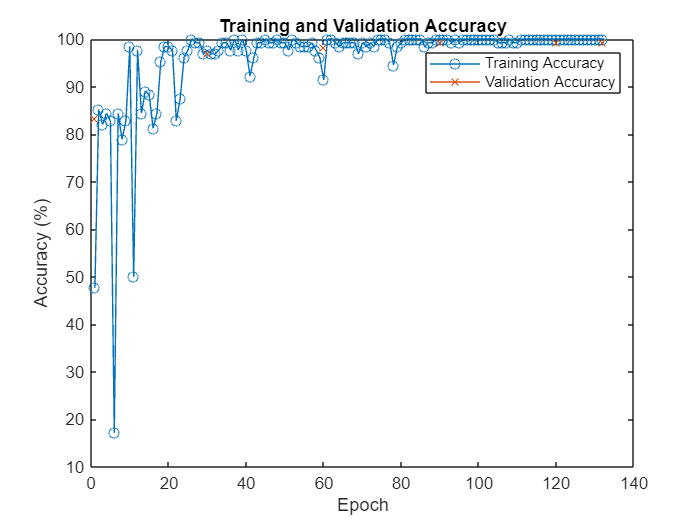


% Plot training and validation accuracy for visual comparison
figure;
plot(1:length(trainAcc), trainAcc, '-o');
hold on;
plot(1:length(valAcc), valAcc, '-x');
xlabel('Epoch');
ylabel('Accuracy (%)');
title('Training and Validation Accuracy');
legend('Training Accuracy', 'Validation Accuracy');
hold off;


% Classify the test data and calculate accuracy
YPred = classify(net, XTest);
accuracy = sum(YPred == YTest) / numel(YTest);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 99.05%


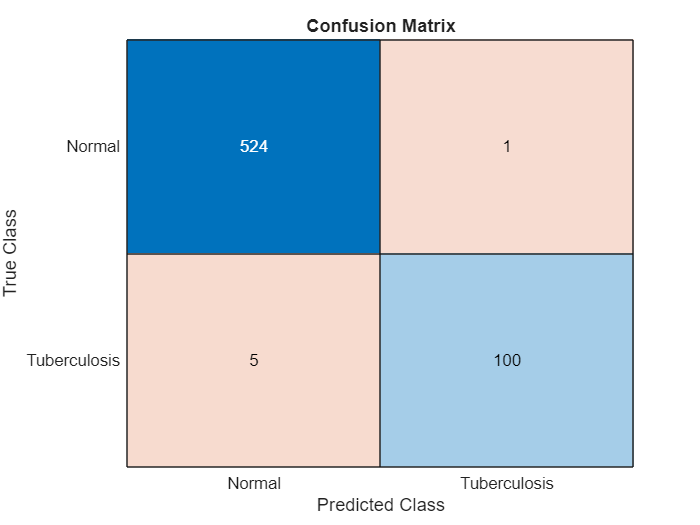


% Display confusion matrix
figure;
ConfMat = confusionmat(YTest, YPred);
confusionchart(YTest, YPred);
title('Confusion Matrix');


% Analyze the network
analyzeNetwork(layers);

% Calculate Precision, Recall, and F1 Score
TP = ConfMat(2, 2); % True Positives (Tuberculosis correctly predicted)
FP = ConfMat(1, 2); % False Positives (Normal misclassified as Tuberculosis)
FN = ConfMat(2, 1); % False Negatives (Tuberculosis misclassified as Normal)
TN = ConfMat(1, 1); % True Negatives (Normal correctly predicted)

precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);
fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 99.01%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 95.24%


fprintf('F1 Score: %.2f\n', f1_score);

F1 Score: 0.97



% Calculate AUC and ROC curve
[~, scores] = classify(net, XTest);
[Xroc, Yroc, ~, AUC] = perfcurve(YTest, scores(:, 2), 'Tuberculosis');
fprintf('AUC: %.4f\n', AUC);

AUC: 0.9800


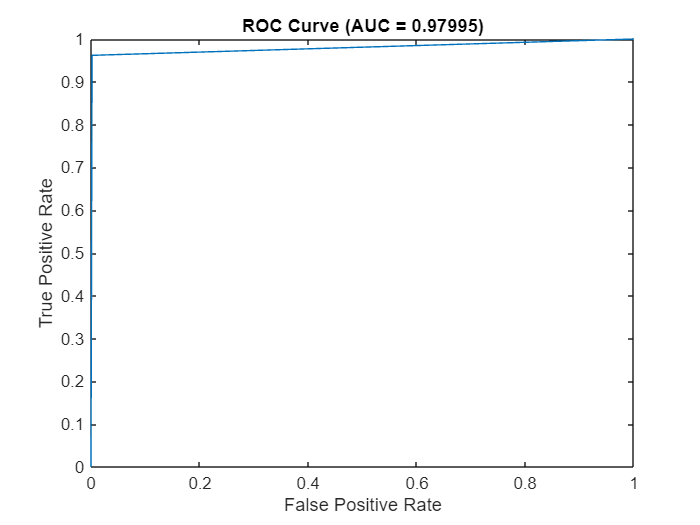


% Plot ROC curve
figure;
plot(Xroc, Yroc);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ' num2str(AUC) ')']);

specificity=(TN)/(TN+FN)

specificity = 0.9905

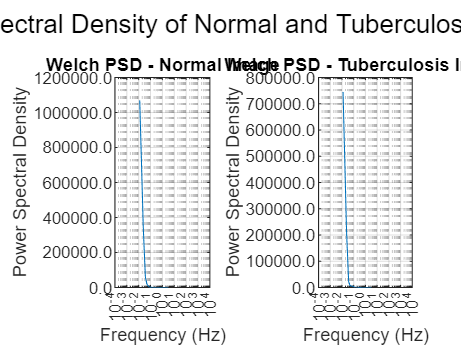

rng(45);  % Set random seed for reproducibility
classNormal = "Normal";
classTB = "Tuberculosis";
dataFolder = "C:\Users\Avrajit\Downloads\TB_Chest_Radiography_Database";
LungImds = imageDatastore(dataFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Find indices for both classes
idxClassNormal = find(LungImds.Labels == classNormal);
idxClassTB = find(LungImds.Labels == classTB);

% Randomly select one image from each class
selectedNormalIndex = randsample(idxClassNormal, 1);
selectedTBIndex = randsample(idxClassTB, 1);

% Define parameters for Welch's method
window = hamming(256);  % Hamming window of length 256
noverlap = 128;         % 50% overlap
nfft = 512;             % Number of FFT points

% Prepare figure for PSD plot
figure;

% Plot for Normal Image
imgNormal = readimage(LungImds, selectedNormalIndex);
if size(imgNormal, 3) == 3
    imgNormal = rgb2gray(imgNormal);
end
imgNormal1D = double(imgNormal(:));
[psdNormal, fNormal] = pwelch(imgNormal1D, window, noverlap, nfft, 'psd');

subplot(1, 2, 1); % One row, two columns, first subplot
semilogx(fNormal, psdNormal);
title('Welch PSD - Normal Image');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density');
xlim([10^-4, 10^4]); % Set frequency range
xticks([10^-4, 10^-3, 10^-2, 10^-1, 10^0, 10^1, 10^2, 10^3, 10^4]); % Set ticks
grid on; % Turn on grid

% Get y-ticks and format them without powers of 10
currentYTicks = get(gca, 'YTick');
set(gca, 'YTick', currentYTicks); % Retain the y-ticks
set(gca, 'YTickLabel', arrayfun(@(x) sprintf('%.1f', x), currentYTicks, 'UniformOutput', false)); % Format y-ticks

% Plot for Tuberculosis Image
imgTB = readimage(LungImds, selectedTBIndex);
if size(imgTB, 3) == 3
    imgTB = rgb2gray(imgTB);
end
imgTB1D = double(imgTB(:));
[psdTB, fTB] = pwelch(imgTB1D, window, noverlap, nfft, 'psd');

subplot(1, 2, 2); % Second subplot
semilogx(fTB, psdTB);
title('Welch PSD - Tuberculosis Image');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density');
xlim([10^-4, 10^4]); % Set frequency range
xticks([10^-4, 10^-3, 10^-2, 10^-1, 10^0, 10^1, 10^2, 10^3, 10^4]); % Set ticks
grid on; % Turn on grid

% Format y-axis ticks for tuberculosis plot without powers of 10
currentYTicksTB = get(gca, 'YTick');
set(gca, 'YTick', currentYTicksTB); % Retain the y-ticks
set(gca, 'YTickLabel', arrayfun(@(x) sprintf('%.1f', x), currentYTicksTB, 'UniformOutput', false)); % Format y-ticks

% Finalize the figure
sgtitle('Power Spectral Density of Normal and Tuberculosis Images');


disp('Welch PSD plots for Normal and Tuberculosis images completed.');

Welch PSD plots for Normal and Tuberculosis images completed.


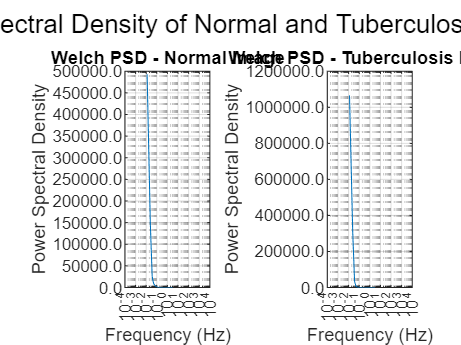

rng(15);  % Set random seed for reproducibility
classNormal = "Normal";
classTB = "Tuberculosis";
dataFolder = "C:\Users\Avrajit\Downloads\TB_Chest_Radiography_Database";
LungImds = imageDatastore(dataFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Find indices for both classes
idxClassNormal = find(LungImds.Labels == classNormal);
idxClassTB = find(LungImds.Labels == classTB);

% Randomly select one image from each class
selectedNormalIndex = randsample(idxClassNormal, 1);
selectedTBIndex = randsample(idxClassTB, 1);

% Define parameters for Welch's method
window = hamming(256);  % Hamming window of length 256
noverlap = 128;         % 50% overlap
nfft = 512;             % Number of FFT points

% Prepare figure for PSD plot
figure;

% Plot for Normal Image
imgNormal = readimage(LungImds, selectedNormalIndex);
if size(imgNormal, 3) == 3
    imgNormal = rgb2gray(imgNormal);
end
imgNormal1D = double(imgNormal(:));
[psdNormal, fNormal] = pwelch(imgNormal1D, window, noverlap, nfft, 'psd');

subplot(1, 2, 1); % One row, two columns, first subplot
semilogx(fNormal, psdNormal);
title('Welch PSD - Normal Image');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density');
xlim([10^-4, 10^4]); % Set frequency range
xticks([10^-4, 10^-3, 10^-2, 10^-1, 10^0, 10^1, 10^2, 10^3, 10^4]); % Set ticks
grid on; % Turn on grid

% Get y-ticks and format them without powers of 10
currentYTicks = get(gca, 'YTick');
set(gca, 'YTick', currentYTicks); % Retain the y-ticks
set(gca, 'YTickLabel', arrayfun(@(x) sprintf('%.1f', x), currentYTicks, 'UniformOutput', false)); % Format y-ticks

% Plot for Tuberculosis Image
imgTB = readimage(LungImds, selectedTBIndex);
if size(imgTB, 3) == 3
    imgTB = rgb2gray(imgTB);
end
imgTB1D = double(imgTB(:));
[psdTB, fTB] = pwelch(imgTB1D, window, noverlap, nfft, 'psd');

subplot(1, 2, 2); % Second subplot
semilogx(fTB, psdTB);
title('Welch PSD - Tuberculosis Image');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density');
xlim([10^-4, 10^4]); % Set frequency range
xticks([10^-4, 10^-3, 10^-2, 10^-1, 10^0, 10^1, 10^2, 10^3, 10^4]); % Set ticks
grid on; % Turn on grid

% Format y-axis ticks for tuberculosis plot without powers of 10
currentYTicksTB = get(gca, 'YTick');
set(gca, 'YTick', currentYTicksTB); % Retain the y-ticks
set(gca, 'YTickLabel', arrayfun(@(x) sprintf('%.1f', x), currentYTicksTB, 'UniformOutput', false)); % Format y-ticks

% Finalize the figure
sgtitle('Power Spectral Density of Normal and Tuberculosis Images');


disp('Welch PSD plots for Normal and Tuberculosis images completed.');

Welch PSD plots for Normal and Tuberculosis images completed.


wordfile = export("tb2.mlx","C:\Users\Avrajit\Downloads\tb2.pdf", ...
    HideCode=true,PageSize="A4",Orientation="Landscape")

wordfile = 'C:\Users\Avrajit\Downloads\tb2.pdf'